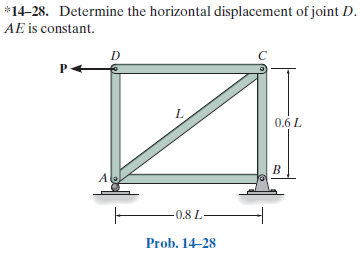

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-28P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-28P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(0.6/0.8))*u.deg;
L = sym('L', 'positive');
jointA = [0 0]*L;
jointB = [0.8 0]*L;
jointC = [0.8 0.6]*L;
jointD = [0 0.6]*L;

# member data

P = sym('P', 'positive');
E = sym('E');
A = sym('A');

# truss

t = Truss;
t = t.add('reaction', 'Ra', {0 'Ray'}, jointA);
t = t.add('reaction', 'Rb', {'Rbx' 'Rby'}, jointB);
t = t.add('concentrated', 'Pd', [-P 0], jointD);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('member', 'Fab', jointA, jointB);
t = t.add('member', 'Fbc', jointB, jointC);
t = t.add('member', 'Fcd', jointC, jointD);
t = t.add('member', 'Fad', jointA, jointD);
t = t.add('member', 'Fac', jointA, jointC);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua

$$ua = \left(\begin{array}{cc} \mathrm{uA} & -\frac{4\,L\,P}{5\,A\,\text{E}}\\ \mathrm{vA} & 0\\ \mathrm{uB} & 0\\ \mathrm{vB} & 0\\ \mathrm{uC} & -\frac{27\,L\,P}{10\,A\,\text{E}}\\ \mathrm{vC} & \frac{9\,L\,P}{20\,A\,\text{E}}\\ \mathrm{uD} & -\frac{7\,L\,P}{2\,A\,\text{E}}\\ \mathrm{vD} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fab} & P\\ \mathrm{Fbc} & \frac{3\,P}{4}\\ \mathrm{Fcd} & P\\ \mathrm{Fad} & 0\\ \mathrm{Fac} & -\frac{5\,P}{4} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & \frac{3\,P}{4} & 0\\ \mathrm{Rb} & P & -\frac{3\,P}{4} & 0\\ \mathrm{Pd} & -P & 0 & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fab} & P & 0 & 0\\ \mathrm{Fbc} & 0 & \frac{3\,P}{4} & 0\\ \mathrm{Fcd} & -P & 0 & 0\\ \mathrm{Fad} & 0 & 0 & 0\\ \mathrm{Fac} & -P & -\frac{3\,P}{4} & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & \frac{3\,P}{4}\\ \mathrm{Rb} & \frac{5\,P}{4}\\ \mathrm{Pd} & P \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & \frac{3\,L\,P}{5}\\ \mathrm{Fcd} & \frac{3\,L\,P}{5}\\ \mathrm{Fad} & 0\\ \mathrm{Fac} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rb} & 0 & 0 & -\frac{3\,L\,P}{5}\\ \mathrm{Pd} & 0 & 0 & \frac{3\,L\,P}{5} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & \frac{3\,L\,P}{5}\\ \mathrm{Fcd} & 0 & 0 & \frac{3\,L\,P}{5}\\ \mathrm{Fad} & 0 & 0 & 0\\ \mathrm{Fac} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rb} & \frac{3\,L\,P}{5}\\ \mathrm{Pd} & \frac{3\,L\,P}{5} \end{array}\right)$$

# clean up

clear ma_f_m ma_f_c la_f_c la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;
new_assum = assumptions;